# Estimate active layer thickness trends using baseflow recession analysis

This script runs the analysis for the Kuparuk River Basin reported in Cooper et al. 2023, [Detecting Permafrost Active Layer Thickness Change From Nonlinear Baseflow Recession](https://doi.org/10.1029/2022WR033154). 

Notes for users:

- This demo is designed to replicate the experiment noted above, therefore it may use different notation, terminology, or other conventions than the current toolbox version.

- Detecting recession events is reasonably fast but fitting events is slow.

- Computing uncertainties is very slow because it uses a bootstrap fit.

- Therefore, an option is included to either run each step or load pre-computed data.

- In typical use, one might run this script once to generate the 'Events' data and save that.

- Then experiment with the 'fitevents' function and save the 'Fits' data.

- Then experiment with the 'globalfit' function and save the 'GlobalFit' data.

clearvars
close all
clc

Set the main options

savedata    = false;
sitename    = baseflow.basinname('KUPARUK R NR DEADHORSE AK');
t1          = datetime(1990,1,1);   % start at 1990 for CALM
t2          = datetime(2020,12,31);
fitevents   = true; % if true, run fitevents, otherwise load saved Fits
fitglobal   = true; % if true, run globalfit, otherwise load saved GlobalFit
plotfigs    = true; % if true, globalfit will produce figures
bootfit     = false; % if true, bootstrap uncertainties (very slow)
nreps       = 1000; % number of bootstrap samples


Set the filename to save the Events, Fits, and GlobalFit .mat files.

fname = fullfile(baseflow.internal.basepath('data'), 'Events.mat');

Set the basin geomorphological parameters

A  = 8.6545e9;       % basin area
Dd = 0.8;            % drainage density
D  = 0.47;           % reference aquifer thickness (mean alt from CALM)
L  = A*Dd/1000;      % active stream length

Load the streamflow data and the CALM-network active layer thickness data

[T, Q, R, Data] = baseflow.loadExampleData('kuparuk');

Set the algorithm options. Here we use a combination of default options and site-specific options.

opts.getevents = baseflow.setopts('getevents', 'asannual', true);
opts.fitevents = baseflow.setopts('fitevents');
opts.globalfit = baseflow.setopts('globalfit', ...
   'drainagearea', A, 'aquiferdepth', D, ...
   'streamlength', L, 'drainagedensity', Dd, ...
   'bootfit', bootfit, 'bootreps', nreps, 'plotfits', true);

Get all recession events and then fit them

if fitevents == true
   [Events, Info] = baseflow.wrapevents(T, Q, R, opts.getevents);
   [Fits, K] = baseflow.fitevents(Events, opts.fitevents);

   if savedata == true
      save(fname,'Events','Fits','K','opts');
   end

else % load pre-saved data
   load(fname,'Events','Fits','K','opts');
end

Run the global fitting analysis. Uncertainties will only be computed if bootfit == true (very slow).

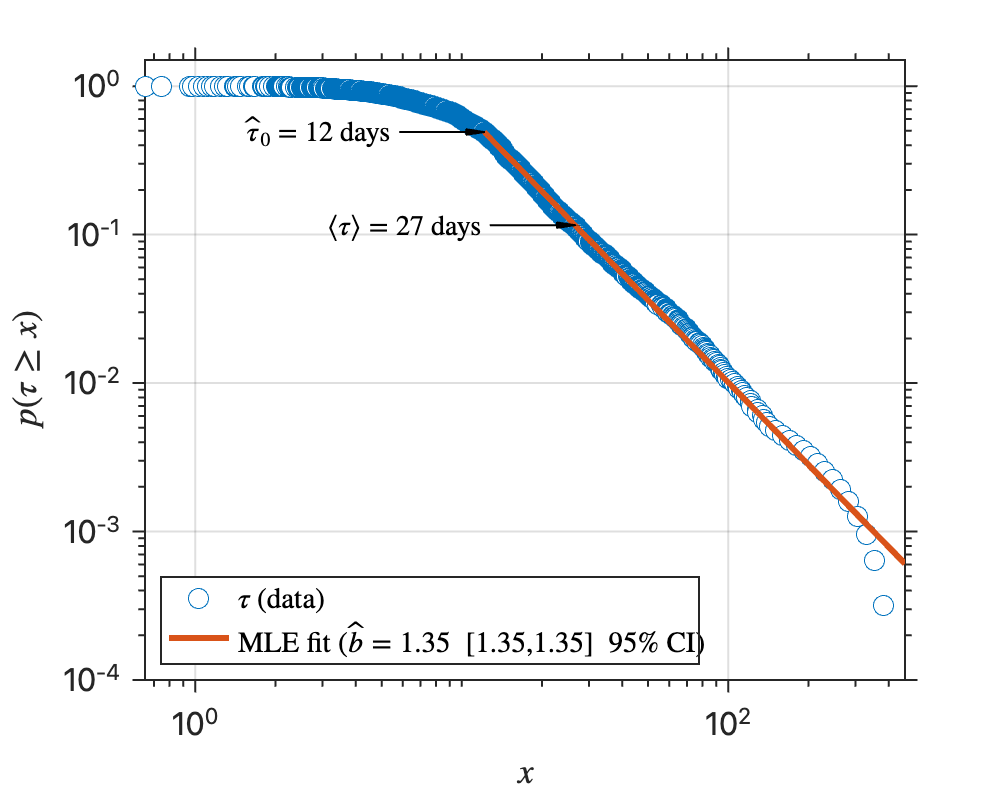

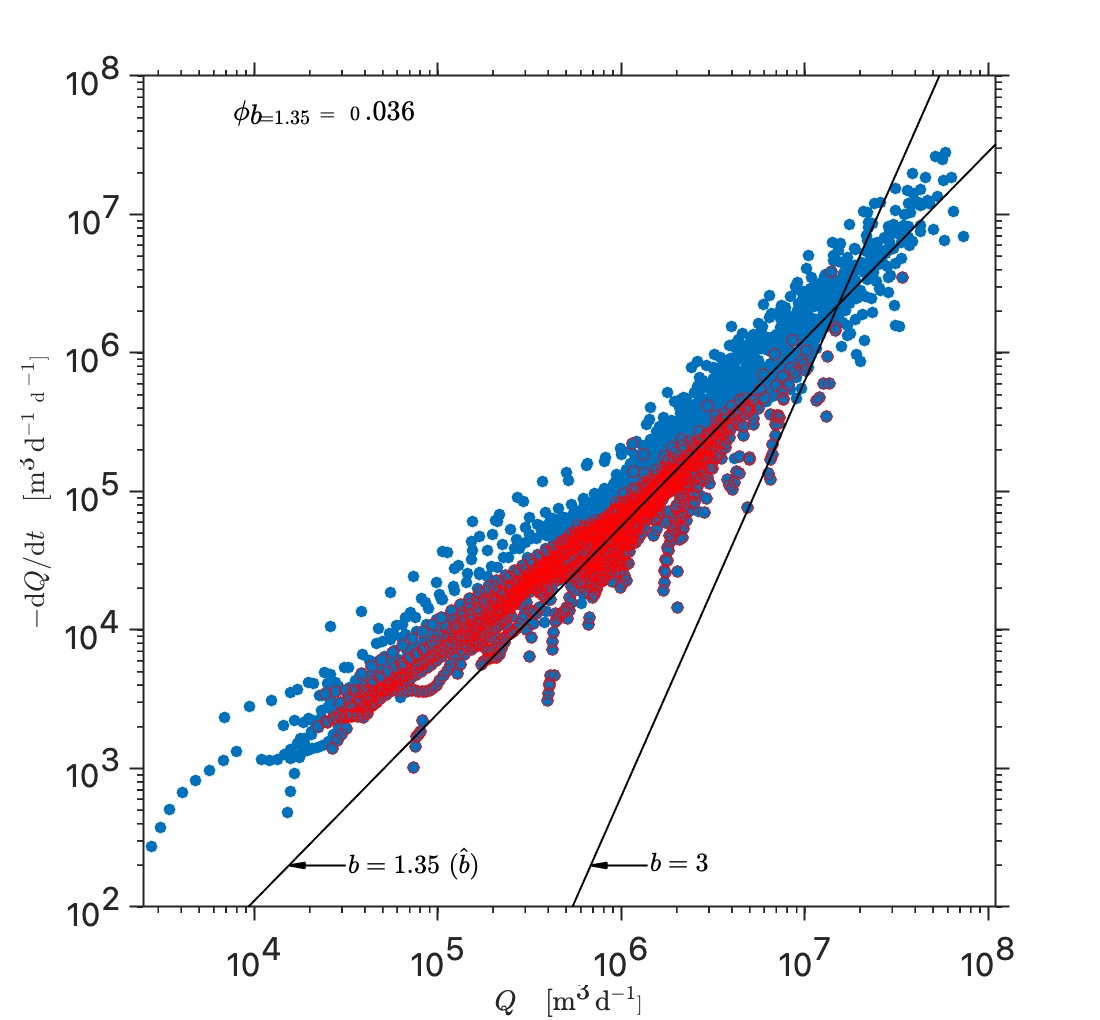

if fitglobal == true

   GlobalFit = baseflow.globalfit(K, Events, Fits, opts.globalfit);

   if savedata == true
      save(fname, 'Events', 'Fits', 'K', 'GlobalFit', 'opts');
   end

else % load pre-saved data
   load(fname, 'Events', 'Fits', 'K', 'GlobalFit', 'opts');
end

Take out parameters and data needed for the next steps

bhat = GlobalFit.b;
pQexp = GlobalFit.pQexp;
tauexp = GlobalFit.tau;
phihat = GlobalFit.phi;

Compute baseflow and aquifer thickness trends

[Qb, ~, Qa, ~, hb] = baseflow.baseflowtrend(T, Q, A, ...
   'pctl', pQexp, 'showfig', false); % cm/d/y

[Db, Sb] = baseflow.aquiferthickness( ...
   bhat, tauexp, phihat, Qb, true); % cm/yr

Qb = Qb.*365.25; % convert from cm/d/yr to cm/yr/yr

Compute the combined uncertainty

sig_dndt = baseflow.dndtuncertainty( ...
   T, Qb, K, Fits, GlobalFit, opts.globalfit, 0.05);

Add the baseflow recession analysis timeseries to the annual Data table, 

Data = addvars(Data, Qb, Sb, Db);
Data.sigDb = Data.Db.*sig_dndt;

Make separate tables for the Grace period and Calm period

inanC = isnan(Data.Dc);%  | isnan(Data.Q);
DataC = Data(~inanC, :);
DataG = DataC(find(year(DataC.Time) == 2002):end, :);

Plot the alt trend

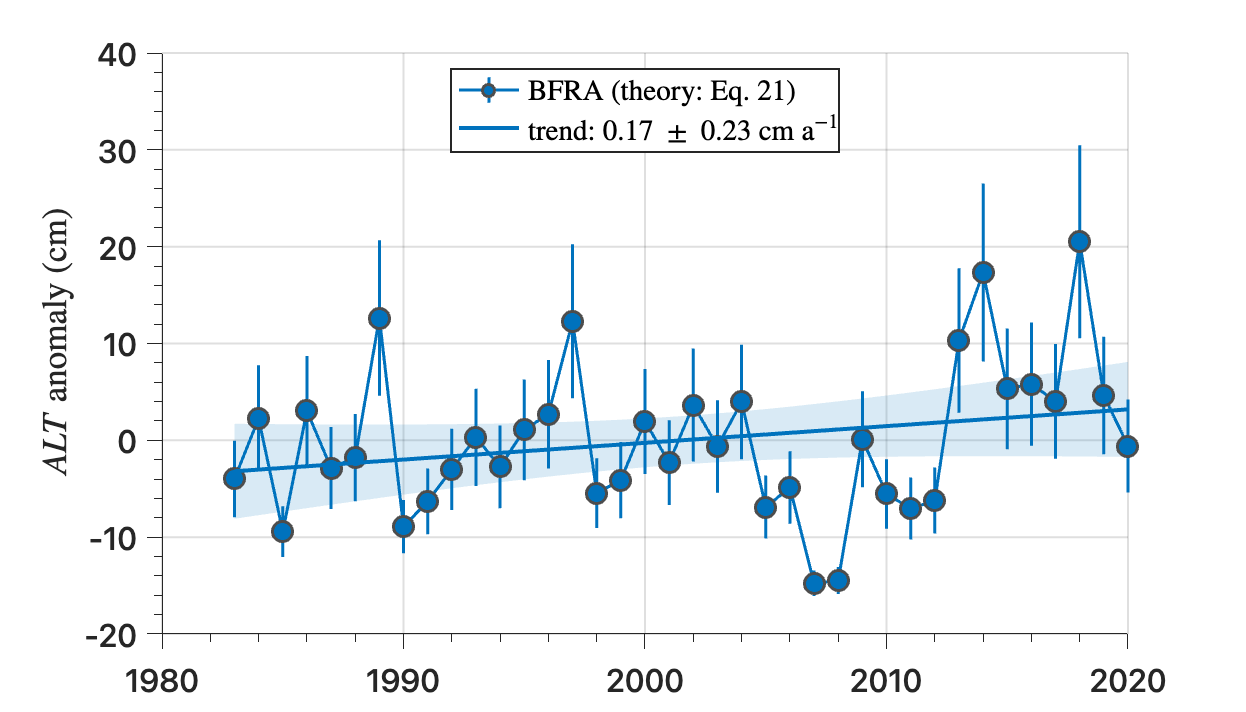

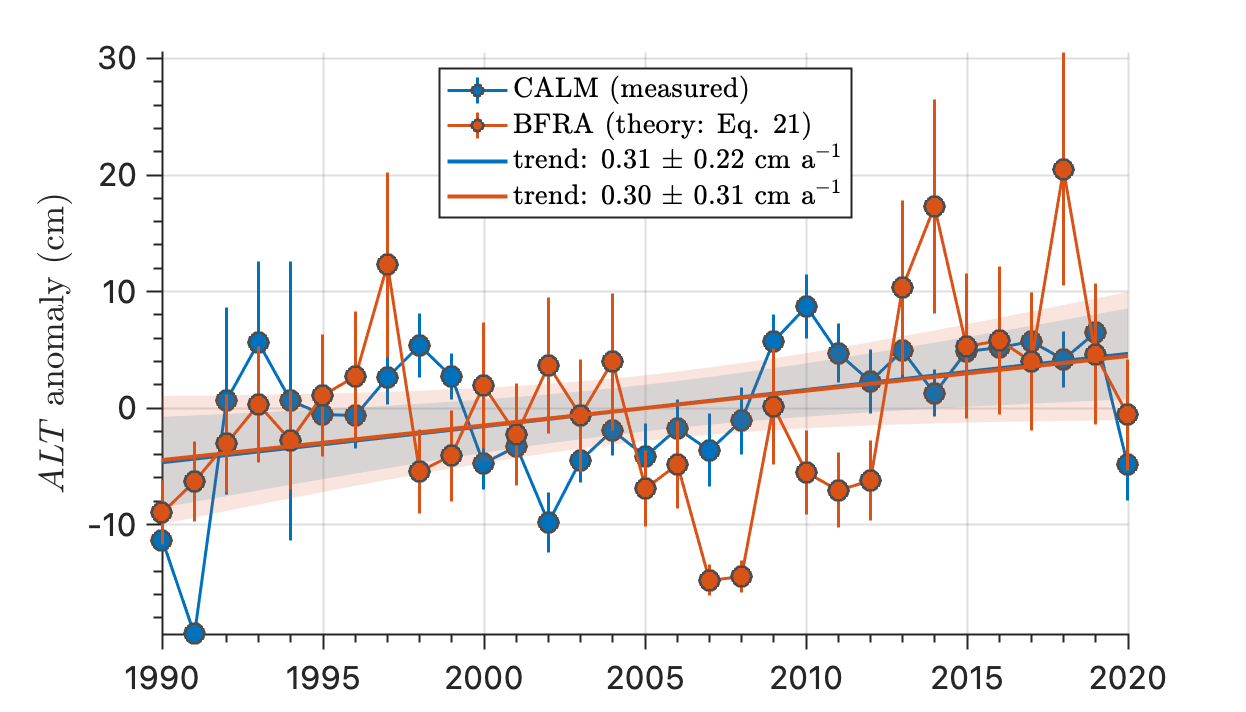

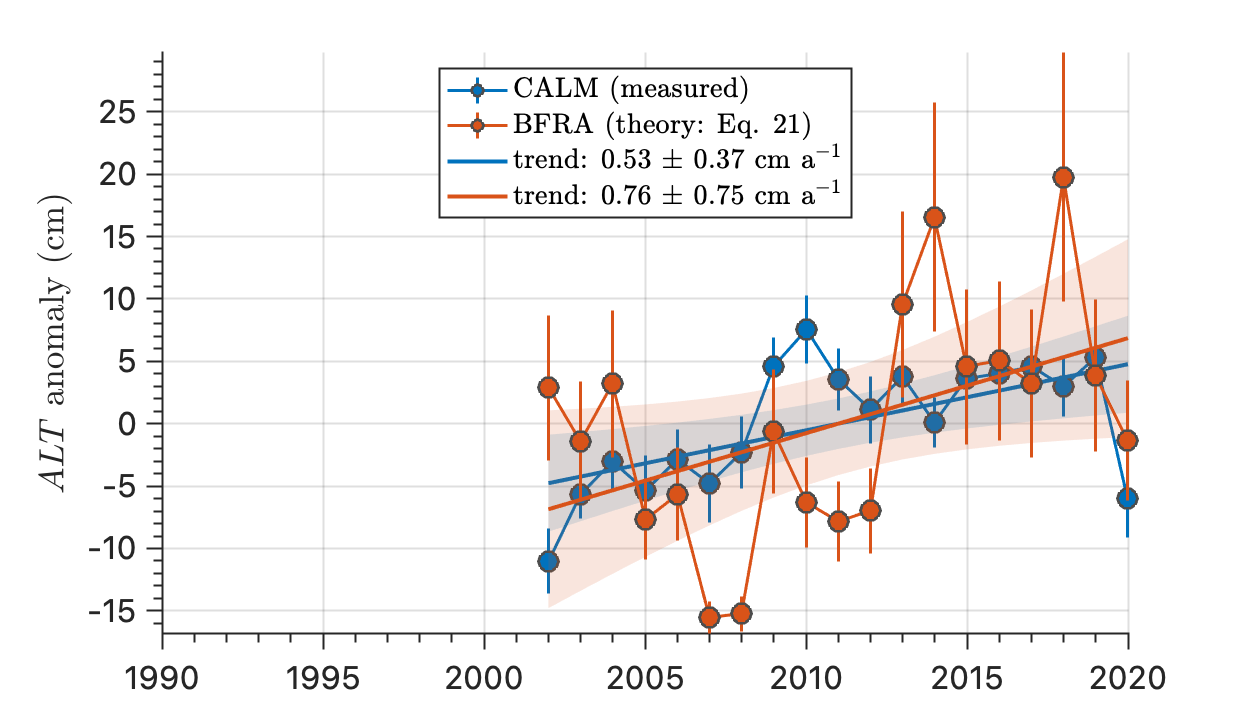

if plotfigs == true
   baseflow.plotaquifertrend(Data.Time, Data.Db, Data.sigDb);

   baseflow.plotaquifertrend(DataC.Time, DataC.Db, DataC.sigDb, ...
      DataC.Dc, DataC.sigDc);

   baseflow.plotaquifertrend(DataG.Time, DataG.Db, DataG.sigDb, ...
      DataG.Dc, DataG.sigDc);
end

Save the data

if savedata == true
   save(fname, ...
      'Events','Fits','K','GlobalFit','Data','DataC','DataG','opts');
end